%

# **信道衰落模拟**

自由空间中，信号没有散射、折射、反射等导致能量损失的情况。因此在通信系统中得到系统的损耗表达式为：


$$ L_f = \frac{P_t}{P_r}=(\frac{4\pi d}{\lambda})^2G_rG_t\\$$


%-----------Parameters Setting------------
LightSpeedC=3e8;
BlueTooth=2400*1000000;%hz    
Zigbee=915.0e6;%hz    
Freq=BlueTooth;
TXAntennaGain=0.5;%db
RXAntennaGain=1;%db
PTx=0.001;%watt
sigma=6;%Sigma from 6 to 12 %Principles of communication systems simulation with wireless application P.548
mean=0;
PathLossExponent=2;%Line Of sight

%------------ FRIIS Equation --------------
% Friis free space propagation model:
%        Pt * Gt * Gr * (Wavelength^2)
%  Pr = --------------------------
%        (4 *pi * d)^2 * L

pr_set = [];
for Dref = 0:1:1000
    Wavelength=LightSpeedC/Freq;
    PTxdBm=10*log10(PTx*1000);
    M = Wavelength / (4 * pi * Dref);
    Pr0= PTxdBm + TXAntennaGain + RXAntennaGain - (20*log10(1/M));
    pr_set = [pr_set, Pr0];
end

Wavelength=LightSpeedC/Freq

Wavelength =    0.125000000000000


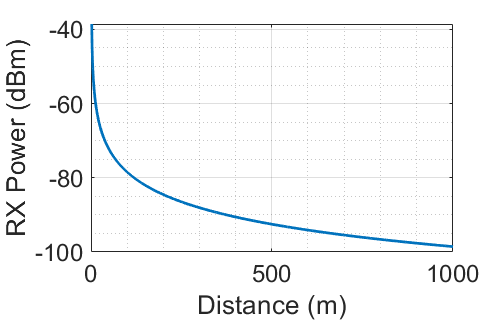


figure;
fg = plot(pr_set);
set(fg,'Linewidth',2);
ylabel('RX Power (dBm)');
xlabel('Distance (m)');
grid on;
set(gca, 'XMinorGrid','on');
set(gca, 'YMinorGrid','on');

set(gcf, 'position', [600 500 500 320]);
set(gca, 'FontSize', 18, 'FontName', 'Arial', 'FontWeight', 'normal');

发射功率对模型结果的影响

%-----------Parameters Setting------------
LightSpeedC=3e8;
BlueTooth=2400*1000000;%hz    
Zigbee=915.0e6;%hz    
Freq=BlueTooth;
TXAntennaGain=0.5;%db
RXAntennaGain=1;%db
PTx=0.001;%watt
sigma=6;%Sigma from 6 to 12 %Principles of communication systems simulation with wireless application P.548
mean=0;
PathLossExponent=2;%Line Of sight

%------------ FRIIS Equation --------------
% Friis free space propagation model:
%        Pt * Gt * Gr * (Wavelength^2)
%  Pr = --------------------------
%        (4 *pi * d)^2 * L

pr_set = [];
for Dref = 0:1:1000
    Wavelength=LightSpeedC/Freq;
    PTxdBm=10*log10(PTx*1000);
    M = Wavelength / (4 * pi * Dref);
    Pr0= PTxdBm + TXAntennaGain + RXAntennaGain - (20*log10(1/M));
    pr_set = [pr_set, Pr0];
end

# 衰落叠加综合

综合看传播路径衰落（Path Loss）、遮挡（Shadowing）、多径（Narrowband Fading）对接收信号的影响（如下图）。Path Loss造成信号衰减是均匀的、单调的；Shadowing造成的衰减相对更快（比Path Loss），断崖下跌；Fading造成的衰减是快速变化的（由于频率高），基本呈现零均值高斯分布。

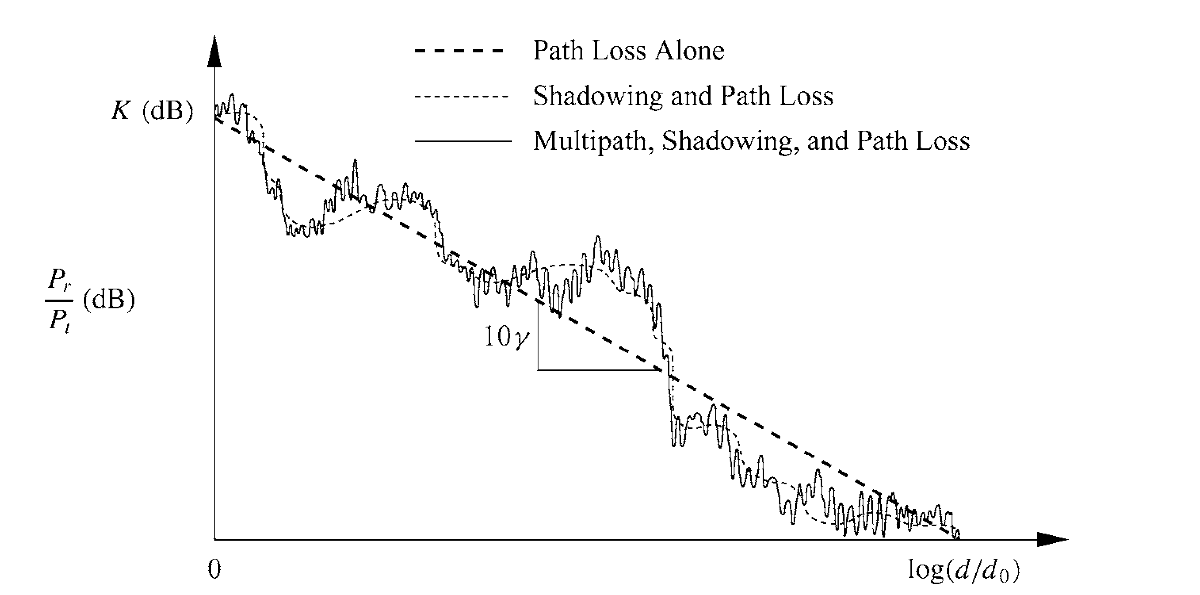

clear;clc
fd=926;     % 最大Doppler
ts_mu=50;   % 持续时间
scale=1e-6;
ts=ts_mu*scale; %采样时间
fs=1/ts;    % sample frequency
Ns=1e5;     % 采样数

M=2^12;
t=(0:Ns-1)*ts;
tt=(0:M-1)*ts;
ff=[-M/2:M/2-1]/(M*ts*fd);
temp=zeros(3,Ns);

%generat channel information
for ii=1:50
    t_state=0;  % 开始采样时刻
    [h,t_state]=Jakes_model(fd,ts,Ns,t_state,1,0);  % generate channel
    yy=xcorr(h);
    yy_cs=xcorr(real(h),imag(h));
    temp(1,:)=temp(1,:)+yy(Ns:length(yy));
    temp(3,:)=temp(3,:)+yy_cs(Ns:length(yy_cs));
end

未定义函数或变量 'Jakes_model'。


figure(1);
subplot(211)
plot((1:Ns)*ts,10*log10(abs(h)));
%axis([0 0.5 -20 5]);
axis([0 0.01 -20 10]);
xlabel('时间/s');ylabel('幅度/db');title('信道时域特性');
str=sprintf('channel model by Jakes with fm=%d[Hz],Ts=%d[us]',fd,ts_mu);
title(str);
% 信道包络
subplot(223)
[f,xi]=ksdensity(abs(h));
plot(xi,f);
cs2=var(h)/2;  %公式乘上了系数sqrt(2)
r=linspace(0,2,1000);
fx2=r./(cs2).*exp(-r.^2/2/(cs2));
hold on;plot(r,fx2,'r:');hold off;
xlabel('幅度');ylabel('统计次数');title('幅度分布');axis([0 2.5 0 1.0]);
% 信道相位
subplot(224)
[f,xi]=ksdensity(angle(h));
plot(xi,f);
hold on;plot([-pi pi],[1/2/pi 1/2/pi],'r:');hold off;
xlabel('相位/rad');ylabel('统计次数');title('相位分布');axis([-pi pi 0 0.2]);


%%自相关函数和功率谱密度
temp(1,:)=temp(1,:)/50;
temp(3,:)=temp(3,:)/50;
%用于归一化
yyy=xcorr(ones(1,Ns));
temp(2,:)=yyy(Ns:length(yy));
%自相关和分量互相关
for k=1:M
    simulated_corr(k)=real(temp(1,k))/temp(2,k);
    simulated_corr_cs(k)=real(temp(3,k))/temp(2,k);
end
classical_corr=besselj(0,2*pi*fd*tt);

%%画图：自相关函数和互相关函数
figure(2);
subplot(211)
plot(tt,classical_corr,'k-',tt,simulated_corr,'r-');
title('自相关函数'); grid on; 
xlabel('时间差/s');ylabel('相关系数');axis([0 0.004 -0.5 1]);
legend('理想特性','仿真结果');
subplot(212)
plot(tt,simulated_corr_cs,'r-');
title('互相关函数'); grid on; 
xlabel('时间差/s');ylabel('相关系数');axis([0 0.004 -0.5 0.5]);
